# SIR Model: Flu Epidemic

## Run the ODE numerical solver

Remember to write the local function SIRmodel at the bottom of this script.

tRange = [0 14];
Y0 = [999; 1; 0];
[tSol,YSol] = ode45(@SIRmodel,tRange,Y0);

## Plot S, I and R vs Time

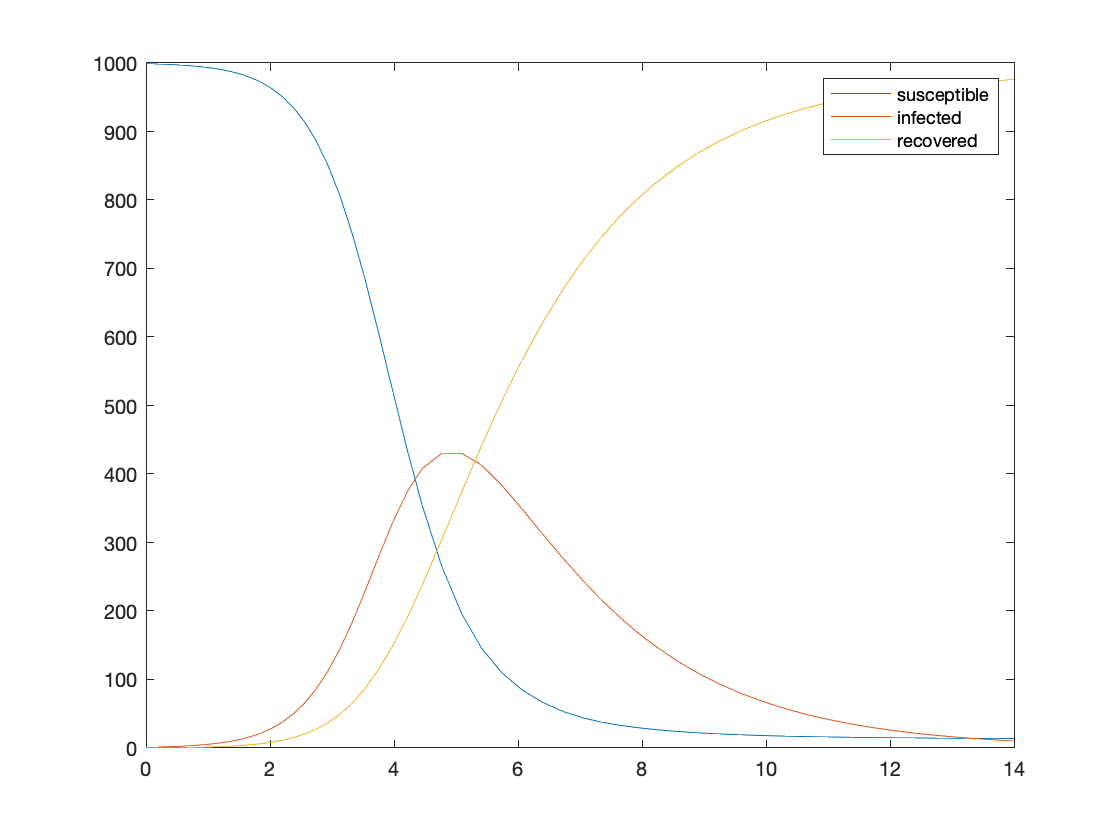

S = YSol(:,1);
I = YSol(:,2);
R = YSol(:,3);

plot(tSol,S)
hold on
plot(tSol,I)
plot(tSol,R)
hold off
legend("susceptible","infected","recovered")

## Find the peak of infected

[maxI,idx] = max(I)

maxI = 430.5016

idx = 46

peakFlu = tSol(idx)

peakFlu = 4.7747

## Find number of uninfected

noFlu = S(end)

noFlu = 13.8939

## Analyse error

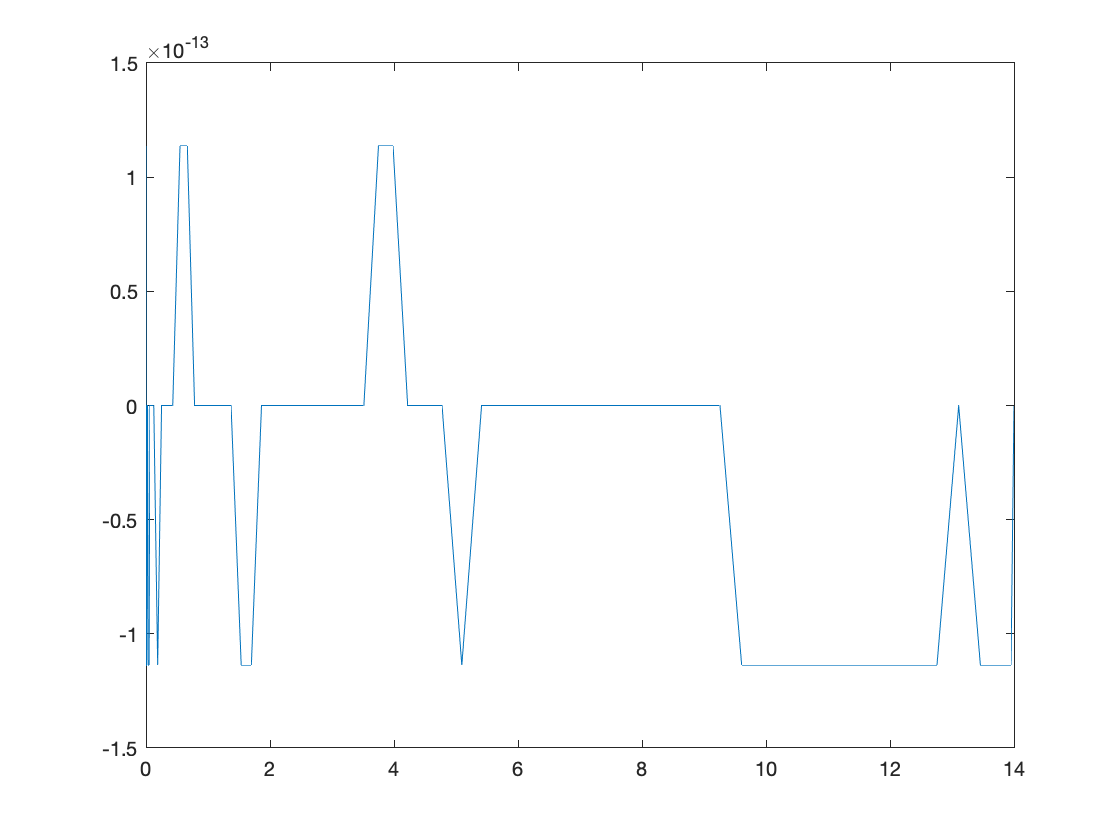

popError = sum(YSol,2) - 1000;
plot(tSol,popError)

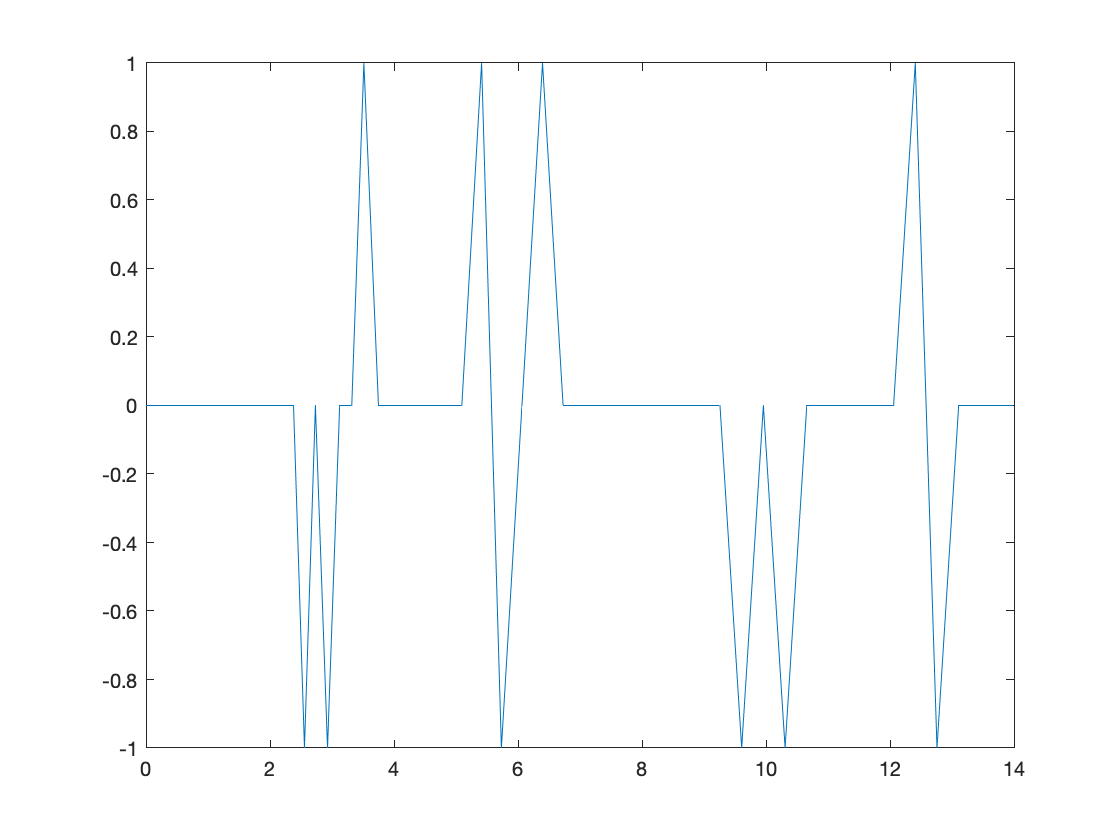


popErrorRnd = sum(round(YSol),2) - 1000;
plot(tSol,popErrorRnd)

## Define the ODE function SIRmodel

function dYdt = SIRmodel(t,Y)  % TODO - Write the function declaration. Name the function SIRmodel
    % Extract S, I, and R from input vector Y
    S = Y(1); % susceptible
    I = Y(2); % infected
    R = Y(3); % recovered
    
    % Define the constants r and a
    r = 0.00218;
    a = 0.5;
    % Define dSdt, dIdt, dRdt from the ODEs
    dSdt = -r*S*I;
    dIdt = r*S*I - a*I;
    dRdt = a*I;
    
    % Create output column vector dYdt
    dYdt = [dSdt; dIdt; dRdt];
end